close all; clear; clc;

syms x y z real
syms r theta phi real
syms R real positive
syms pi
syms csi real positive
syms c real

CSI=(0:1/2:20)';
C=sym(zeros(size(CSI)));

for n=1:length(CSI)
  csi=CSI(n);
  
  S=c*1/(pi*R^3)*(1-(r/R)^2)^csi;
  
  I=1*int(int(int(S*r^2*sin(phi),theta,0,2*pi),phi,0,pi),r,0,R);
  
  C(n)=solve(I==1);
  disp(C(n))
end

$$\frac{3}{4}$$

$$\frac{4}{\pi }$$

$$\frac{15}{8}$$

$$\frac{8}{\pi }$$

$$\frac{105}{32}$$

$$\frac{64}{5\,\pi }$$

$$\frac{315}{64}$$

$$\frac{128}{7\,\pi }$$

$$\frac{3465}{512}$$

$$\frac{512}{21\,\pi }$$

$$\frac{9009}{1024}$$

$$\frac{1024}{33\,\pi }$$

$$\frac{45045}{4096}$$

$$\frac{16384}{429\,\pi }$$

$$\frac{109395}{8192}$$

$$\frac{32768}{715\,\pi }$$

$$\frac{2078505}{131072}$$

$$\frac{131072}{2431\,\pi }$$

$$\frac{4849845}{262144}$$

$$\frac{262144}{4199\,\pi }$$

$$\frac{22309287}{1048576}$$

$$\frac{2097152}{29393\,\pi }$$

$$\frac{50702925}{2097152}$$

$$\frac{4194304}{52003\,\pi }$$

$$\frac{456326325}{16777216}$$

$$\frac{16777216}{185725\,\pi }$$

$$\frac{1017958725}{33554432}$$

$$\frac{33554432}{334305\,\pi }$$

$$\frac{4508102925}{134217728}$$

$$\frac{1073741824}{9694845\,\pi }$$

$$\frac{9917826435}{268435456}$$

$$\frac{2147483648}{17678835\,\pi }$$

$$\frac{347123925225}{8589934592}$$

$$\frac{8589934592}{64822395\,\pi }$$

$$\frac{755505013725}{17179869184}$$

$$\frac{17179869184}{119409675\,\pi }$$

$$\frac{3273855059475}{68719476736}$$

$$\frac{137438953472}{883631595\,\pi }$$

$$\frac{7064634602025}{137438953472}$$

$$\frac{274877906944}{1641030105\,\pi }$$

$$\frac{60755857577415}{1099511627776}$$

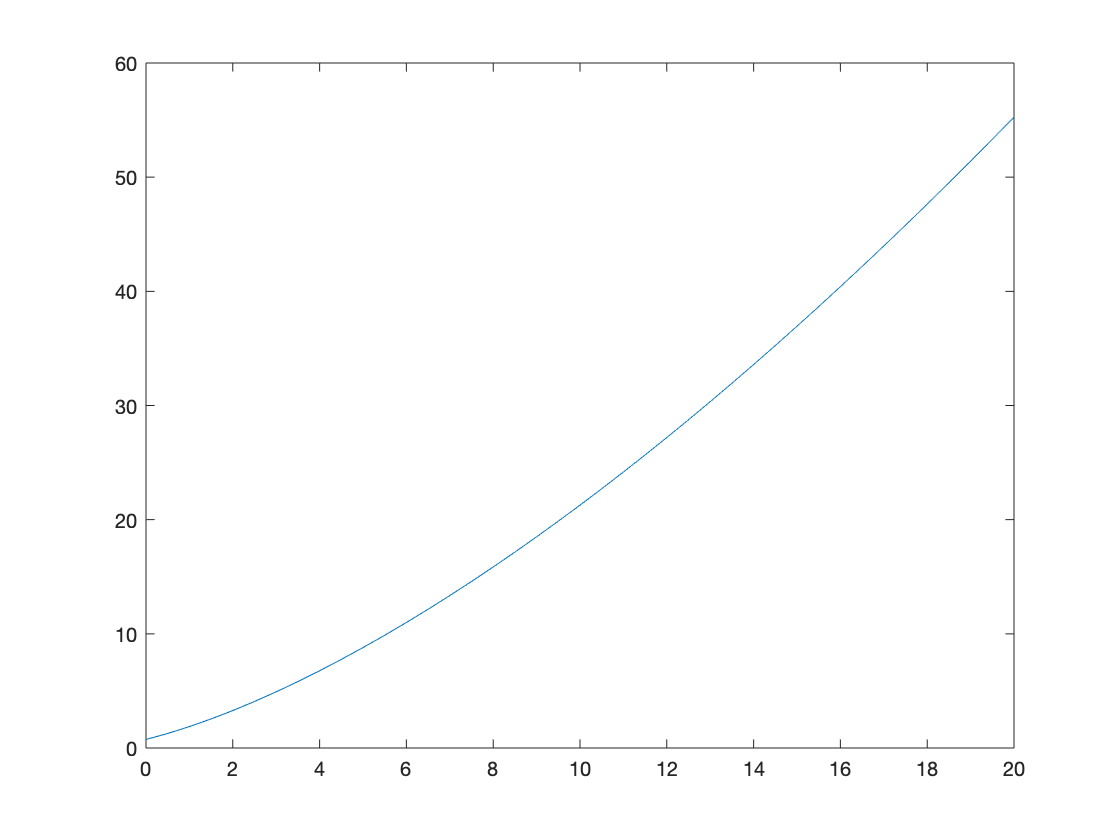


plot(CSI,C)